Companion software for "Volker Ziemann, *Physics and Finance, Springer, 2021*" ([https://link.springer.com/book/10.1007/978-3-030-63643-2](https://link.springer.com/book/10.1007/978-3-030-63643-2))

# $\chi^2$-distribution (Section 7.4)

Volker Ziemann, 211125, CC-BY-SA-4.0

In this example we simply plot the $\chi^2$-distribution function $\psi_n(q)$, defined in Equation 7.22, which shows the distribution of the squares $n$ independet random variables, each with a Gaussian (normal) distribution.

First we use a slider to set the value `n` and define the range of values `q` to plot, before actually plotting the function chisqfun(), which is defined in the appendix. Finally we annotate the axes.

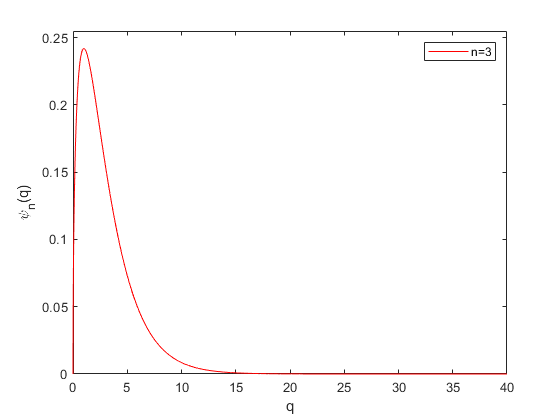

clear
n=3; % Slider to select n
q=0:0.01:40;
plot(q,chisqfun(q,n),'r')
ylim([0,0.255])
xlabel('q')
ylabel('\psi_n(q)')
legend(['n=',num2str(n)])

## Appendix

The function chisqfun() encodes $\psi_n(q)$ defined in Equation 7.22.

function out=chisqfun(q,n)
fact=2^(n/2)*gamma(n/2);
out=q.^(n/2-1).*exp(-q/2)/fact;
end